# European Put via Quadrature

# Suggestion 2: Precompute and Reuse CDF Matrix

tic;

function price = european_quad_smooth (S0, K, r, q, sigma, T, n_steps, m_grid)

% Time-homogeneous grid + efficient implementation:
% c_t = e^{-r h} * F * ( v_{t+h} ∘ w )
% where F(i,j) = f(s_j | s_i) and w are Simpson weights on destination grid.

% 1) Time step and log-price grid (fixed for all steps)
h  = 1/365;                  % use the paper's setting (daily)
s0 = log(S0);

% wide enough to capture prob. mass through T
smin = s0 - 10*(sigma*sqrt(T));
smax = s0 + 10*(sigma*sqrt(T));

% uniform log-price grid
s = linspace(smin, smax, m_grid)';            % m x 1
ds = s(2) - s(1);
S = exp(s);
mid = (m_grid+1)/2;                            % assume m_grid odd

% 2) One-step transition density in log-space (GBM -> Normal)
mu_shift = (r - q - 0.5*sigma^2) * h;
sig_h    = sigma * sqrt(h);

F = zeros(m_grid, m_grid);
dest = s';                                     % 1 x m (destination axis)

for i = 1:m_grid
    mu_i   = s(i) + mu_shift;                  % mean of s_{t+h} | s_t = s(i)
    z      = (dest - mu_i) / sig_h;
    F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*(z.^2));   % row i pdf values
end

% Sparsify tiny tails as in the paper (suggestion #2)
F(F < 1e-10) = 0; F = sparse(F);

% 3) Simpson weights on destination axis
w = ones(m_grid,1);
w(2:2:end-1) = 4;
w(3:2:end-2) = 2;
w = w * (ds/3);                               

% 4) Penultimate-step smoothing (Black–Scholes with maturity h)
% v_{T-h}(s) = European put with time-to-maturity h at spot S=exp(s)
d1  = (log(S./K) + (r - q + 0.5*sigma^2)*h) / (sigma*sqrt(h));
d2  = d1 - sigma*sqrt(h);
Nd1 = 0.5*(1 + erf(d1/sqrt(2)));
Nd2 = 0.5*(1 + erf(d2/sqrt(2)));
A_put = K*exp(-r*h).*(1 - Nd2) - S.*exp(-q*h).*(1 - Nd1);   % smooth v_{T-h}

v_next = A_put;                               % start recursion at T-h
disc   = exp(-r*h);

% 5) Backward propagation: pure continuation (European, no max)
for t = 2:n_steps
    % c_t = e^{-r h} * F * ( v_{t+h} ∘ w )
    v_next = disc * ( F * (v_next .* w) );
end

% time-0 price at S0 (center node)
price = v_next(mid);
end

% Run Euro
S0 = 50;  K = 50;
r = 0.05; q = 0.02; sigma = 0.30;
T = 60/365;              
n_steps = 60;            
m_grid  = 401;           

peuro = european_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_grid);
fprintf('European put (quadrature, T-h smoothing): %.6f\n', peuro);

European put (quadrature, T-h smoothing): 2.290222



toc;

Elapsed time is 0.019327 seconds.


## European Put: Convergence Plots & Table (Simonato quadrature with T−h smoothing)

Black–Scholes references are hard-coded from the paper for K = 50: n = 60 days -> 2.2902 n = 365 days -> 5.0617

S0 = 50;    
r  = 0.05;  
q  = 0.02;
sigma = 0.30;

m_list = 101:2:401;    % Odd grid sizes so s0 sits at center node
n_steps_short = 60;    % 60-day case
n_steps_long  = 365;   % 365-day case

##  Table (K = 50)

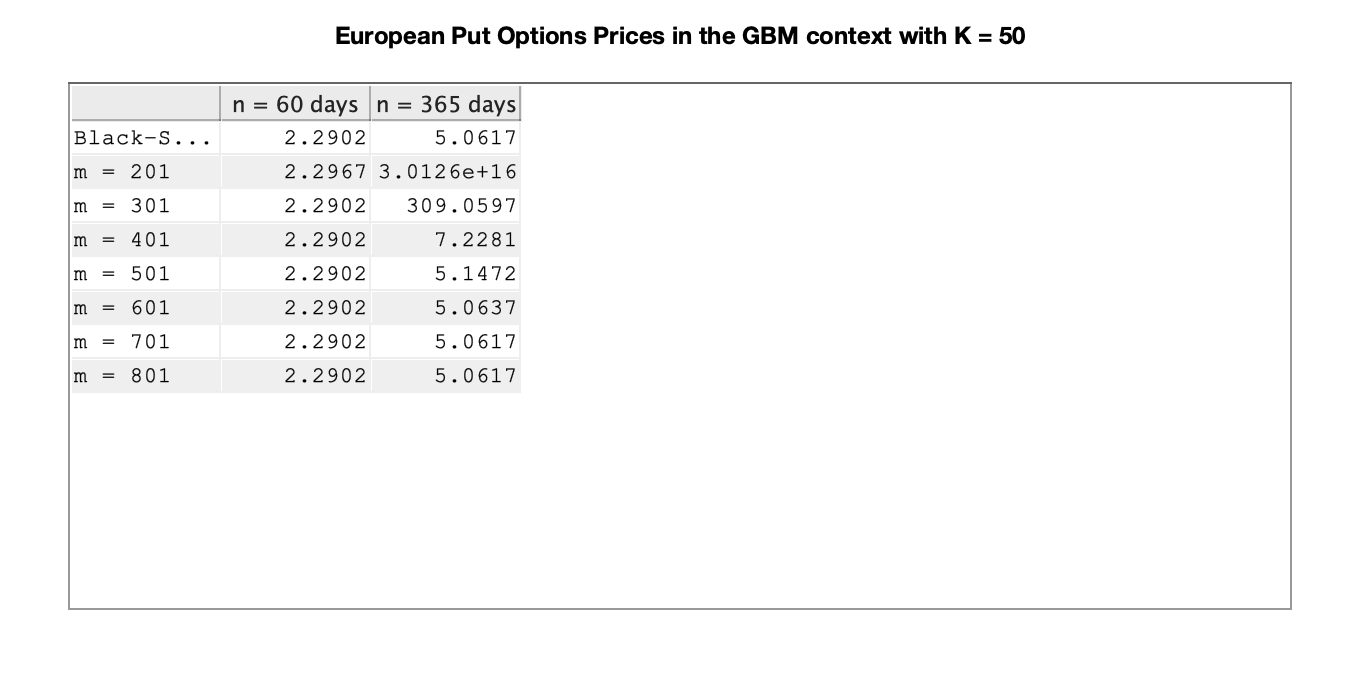

S0 = 50; K = 50; r = 0.05; q = 0.02; sigma = 0.30;

m_vec   = [201 301 401 501 601 701 801]';
T_60    = 60/365;   n_60   = 60;
T_365   = 365/365;  n_365  = 365;

% Quadrature European (Function)
euro_60  = nan(numel(m_vec),1);
euro_365 = nan(numel(m_vec),1);
for j = 1:numel(m_vec)
    m = m_vec(j);
    euro_60(j)  = european_quad_smooth(S0,K,r,q,sigma,T_60, n_60,  m);
    euro_365(j) = european_quad_smooth(S0,K,r,q,sigma,T_365,n_365, m);
end
euro_60_disp  = round(euro_60,  4);
euro_365_disp = round(euro_365, 4);

% Hard-coded Black–Scholes European reference values (paper, K = 50)
BS_60  = 2.2902;
BS_365 = 5.0617;

% Build data: first row BS reference, then quadrature rows
data = cell(numel(m_vec)+1, 3);
data{1,1} = 'Black–Scholes Prices';
data{1,2} = BS_60;
data{1,3} = BS_365;
for j = 1:numel(m_vec)
    data{j+1,1} = sprintf('m = %d', m_vec(j));
    data{j+1,2} = euro_60_disp(j);
    data{j+1,3} = euro_365_disp(j);
end

% Create table window
f = figure('Name','European Put Options Prices in the GBM context with K = 50',...
           'NumberTitle','off','Position',[200 200 680 340],'Color','white');

annotation(f,'textbox',[0 0.90 1 0.08],...
    'String','European Put Options Prices in the GBM context with K = 50',...
    'EdgeColor','none','HorizontalAlignment','center',...
    'FontWeight','bold','FontSize',12);

colnames = {'','n = 60 days','n = 365 days'};
uitable(f,'Data',data,'ColumnName',colnames,'RowName',[],...
    'ColumnEditable',[false false false],'Units','normalized',...
    'Position',[0.05 0.10 0.90 0.78],'FontName','Courier','FontSize',11);